syms t
assume(t, ["real", "positive"])

% Axis of rotation as a function of time
alpha = [
    1;
    0;
    0;
];
alpha = alpha / norm(alpha);
% Angle of rotation as a function of time
theta = 0.2*t;

% Construct the quaternion using axis-angle
q_t = [
    cos(theta/2);
    sin(theta/2)*alpha;
];

%q_t = q_t / norm(q_t);

r_t = [
    0;
    t;
    0;
];

tab_sim = generate_trajectory(tspan, r_t, q_t);

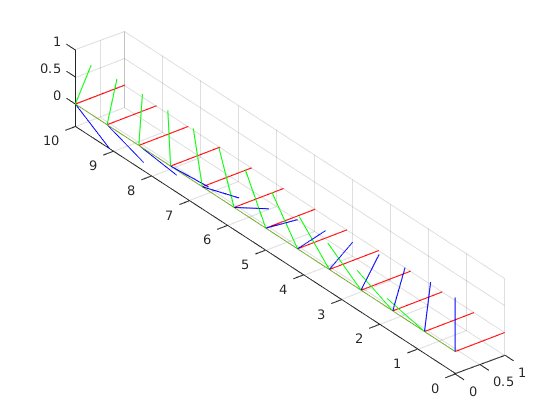

TF frames displayed: 13

viz_trajectory(tab_sim.r, tab_sim.q)